[data_itay,f] = audioread("itay.wav");
sound(data_itay,f);

%itay=audiorecorder (16000,16,1,-1);
%disp('Start speaking.')
%recordblocking(itay,5);
%disp('End of Recording.');
%data_itay= getaudiodata(itay);

%save itay
%sound(data_itay,16000);

נחתוך את ההקלטה לאורך של 2^16

itay_ef=data_itay(1:2^16);%x(n)

חישוב ההספק

p_itay=mean(itay_ef.^2)

p_itay = 3.4493e-04

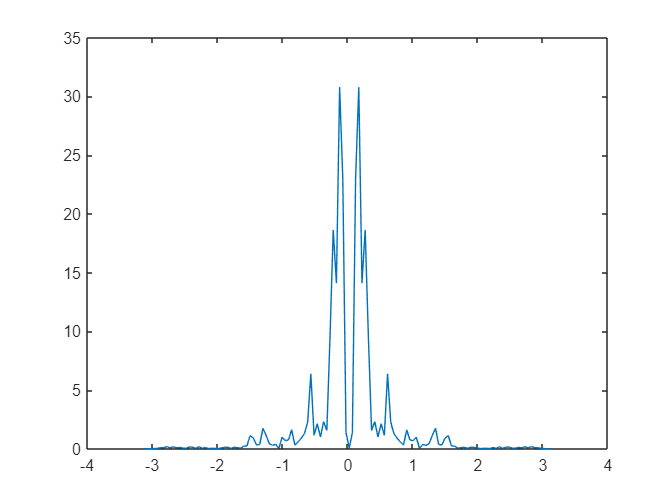

ITAY_ef = fft(itay_ef);
M = 128;
Y_plot = ITAY_ef(1:size(ITAY_ef,1)/M:end);
Y_plot = circshift(Y_plot,M/2);
W = 2*pi/M * (-(M-1)/2:(M-1)/2);
figure
plot(W,abs(Y_plot));

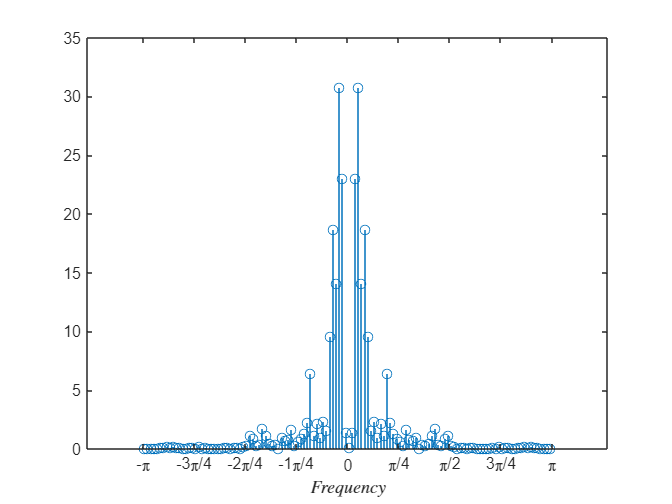




figure
stem(W,abs(Y_plot));
xlabel('$$ Frequency $$','Interpreter','latex'); 
set(gca,'XTick',-pi:pi/4:pi,'XTickLabel',{'-\pi','-3\pi/4','-2\pi/4','-1\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})

אות ההפרעה

n=0:1:2^16-1;%linspace(0,2^16,2^16);%
w1=1.6+0.1*0.316332808;
w2=1.6+0.1*0.025450264;
w3=3;
z_itay=50*sqrt(p_itay)*(cos(n*w1)+cos(n*w2)+cos(n*w3));

האות המופרע (איתי ילד רע)

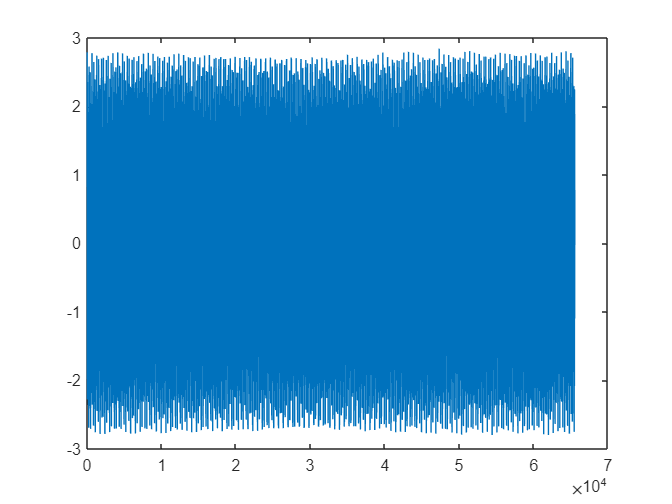

y_itay=itay_ef+z_itay';
plot(y_itay)

עושים לאיתי פעולות המרה(כמו שאפשר לראות איתי הופך להיות ילד גדול)

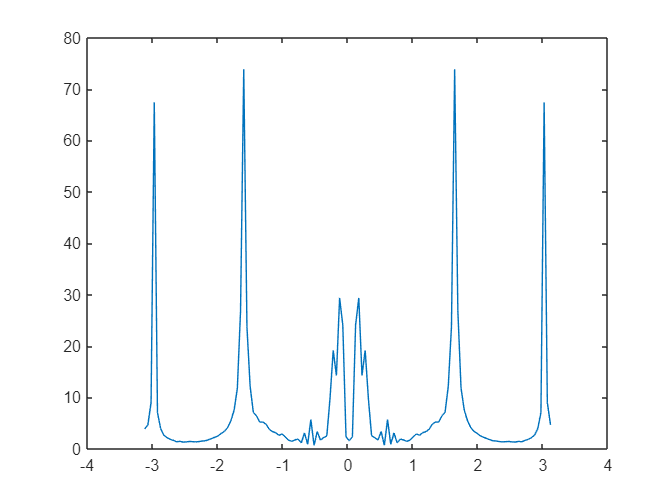

Y_ITAY=fft(y_itay); % dsp_fft(y_itay);
M = 128;
X_plot = Y_ITAY(1:size(Y_ITAY,1)/M:end);
X_plot = circshift(X_plot,M/2);
W = 2*pi/M * [-(M-1)/2:(M-1)/2];
figure
plot(W,abs(X_plot))

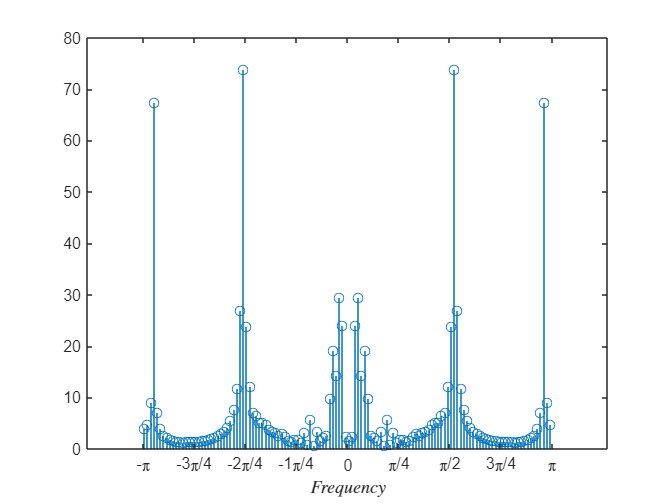




figure
stem(W,abs(X_plot))
xlabel('$$ Frequency $$','Interpreter','latex'); 
set(gca,'XTick',-pi:pi/4:pi,'XTickLabel',{'-\pi','-3\pi/4','-2\pi/4','-1\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})

sound(y_itay,16000);

אפשר לראות בגרף לעיל שאנו מקבבלים 2 זוגות של דלתאות מקבילות, הסיבבה לכך היא שבהתאם לתמסרי הת.ז שלנו אנו מקבלים ערכי אומגה קרובים מאוד כך שהם מתאחדים בהמרה לזוג דלתאות יחיד ועבור התדר השווה 3 נקבל עוד זוג דלתאות.

כעת נבצע דצימציה של פי 2 עבור 

Y ו-Z

y_itay2= y_itay(1:2:2^16);
z_itay2= z_itay(1:2:2^16);

z_itay=50*sqrt(p_itay)*(cos(n*w1)+cos(n*w2)+cos(n*w3)) -> 2~->

N=n*2

z_2(n) = 50*sqrt(p_itay/2)*(cos(N*w1)+cos(N*w2)+cos(N*w3))

Z_2(e^-jw)=50sqrt(p_itay/2)

כעת נצייר את

 y_2ואת Y_2

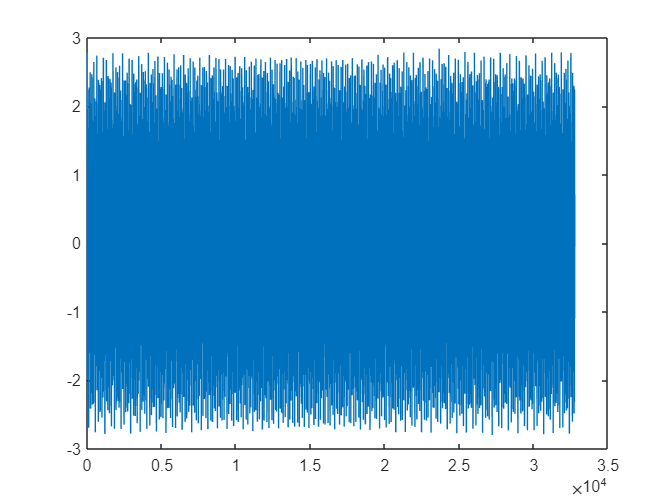

plot(y_itay2)

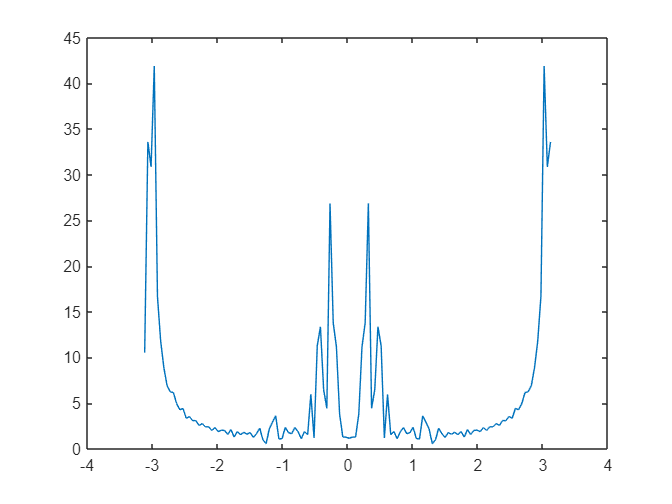

Y_ITAY2=fft(y_itay2);
M = 128;
Y_plot = Y_ITAY2(1:size(Y_ITAY2,1)/M:end);
Y_plot = circshift(Y_plot,M/2);
W = 2*pi/M * (-(M-1)/2:(M-1)/2);
figure
plot(W,abs(Y_plot));

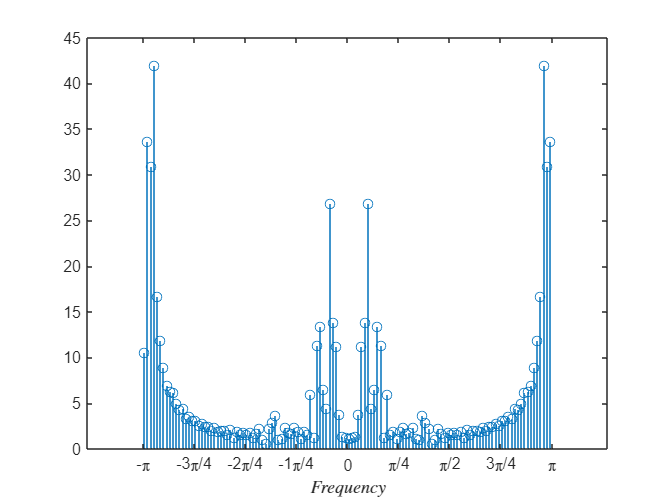

figure
stem(W,abs(Y_plot));
xlabel('$$ Frequency $$','Interpreter','latex'); 
set(gca,'XTick',-pi:pi/4:pi,'XTickLabel',{'-\pi','-3\pi/4','-2\pi/4','-1\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})


sound(y_itay2,f/2);